# **FDS 2024: Field and service robotics**

## `Homework 3 Question 5`

## Andrea Morghen

Let's plot some result from the symulink model:

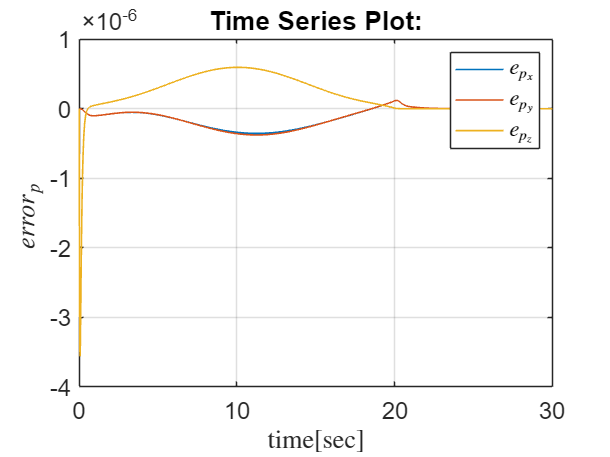

% error_p
figure()
plot(out.err_p,'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$error_p$ ','Interpreter','latex')
grid("on");
hold on
legend('$e_{p_x}$','$e_{p_y}$','$e_{p_z}$','Interpreter', 'latex')
set(gca,'Fontsize',15)

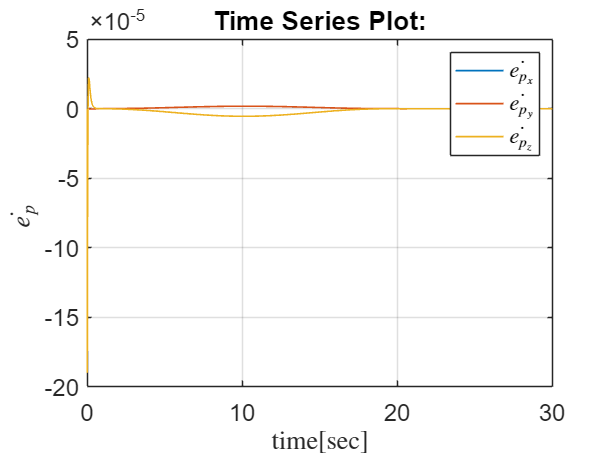


% error_vel
figure()
plot(out.dot_err_p  ,'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$\dot{e_p}$ ','Interpreter','latex')
hold on
legend('$\dot{e_{p_x}}$','$\dot{e_{p_y}}$','$\dot{e_{p_z}}$','Interpreter', 'latex')
grid("on");
set(gca,'Fontsize',15)

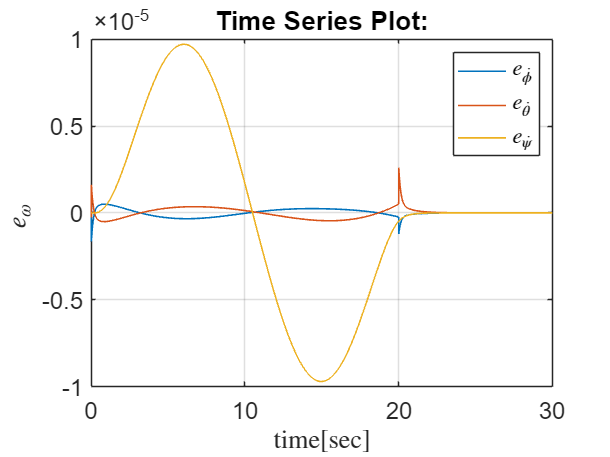


% error_w
figure()
plot(out.err_W,'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$e_{\omega}$ ','Interpreter','latex')
hold on
legend('${e_{\dot{\phi}}}$','${e_{\dot{\theta}}}$','${e_{\dot{\psi}}}$','Interpreter', 'latex')
grid("on");
set(gca,'Fontsize',15)

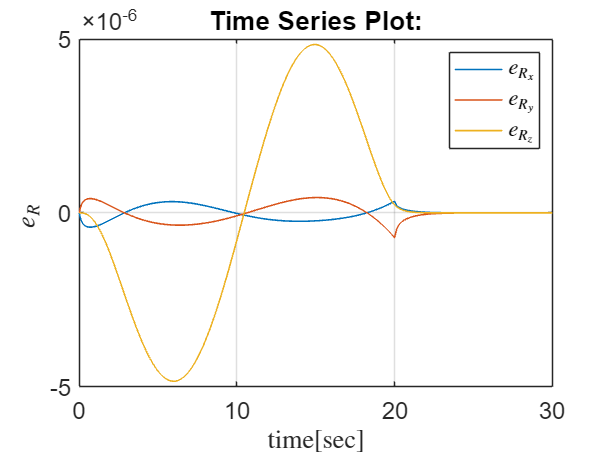


% error_R
figure()
plot(out.err_R,'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$e_{R}$ ','Interpreter','latex')
hold on
legend('$e_{R_x}$','$e_{R_y}$','$e_{R_z}$','Interpreter', 'latex')
grid("on");
set(gca,'Fontsize',15)

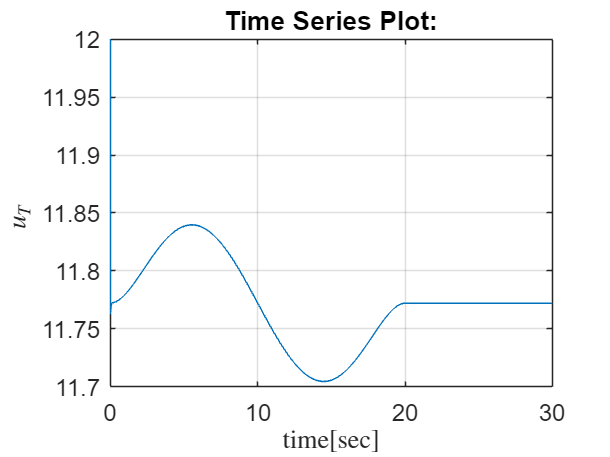



% u_T
figure()
plot(out.uT,'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$u_T$ ','Interpreter','latex')
grid("on");
set(gca,'Fontsize',15)

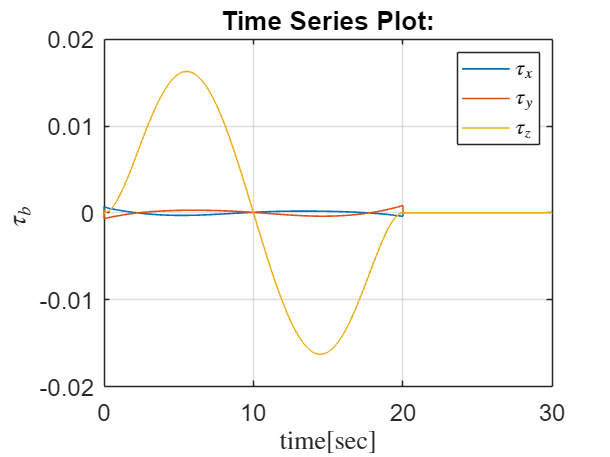


% tau_B
figure()
plot(out.tau_b,'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$\tau_b$ ','Interpreter','latex')
hold on
legend('$\tau_x$','$\tau_y$','$\tau_z$','Interpreter', 'latex')
grid("on");
set(gca,'Fontsize',15)

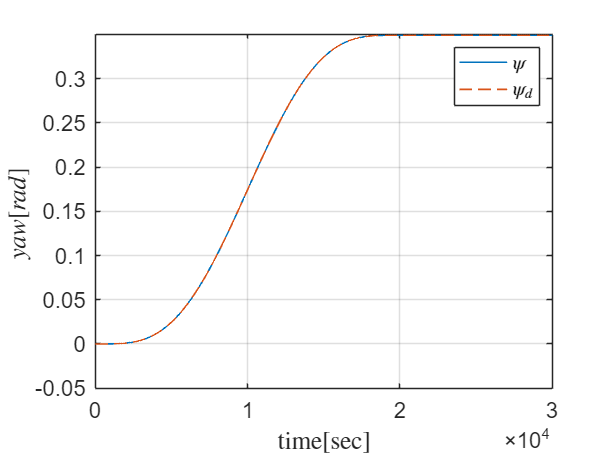



% RPY_deg
yaw=zeros(length(out.tout),1);
for i=1:length(out.tout)
yaw(i)= atan(out.Rb.Data(2,1,i)/out.Rb.Data(1,1,i));
end
% err_yaw=yaw-psi_d';
% figure()
% plot(err_yaw,'lineWidth',1)
figure()
plot(yaw,'lineWidth',1)
hold on
plot(psi_d, '--','lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$yaw [rad]$ ','Interpreter','latex')
grid("on");
hold on
legend('$\psi$','$\psi_d$','Interpreter', 'latex')
set(gca,'Fontsize',14)